
clear; clc; close all;

% Load recorded IQ data
load('RC_IQ.mat');

% Display recording information
fprintf('Center frequency: %.3f GHz\n',fc/1e9);

Center frequency: 2.412 GHz


fprintf('Sampling frequency: %.2f MHz\n',Fs/1e6);

Sampling frequency: 50.00 MHz


fprintf('Number of samples: %d\n',length(IQ));

Number of samples: 5000000


fprintf('Recording duration: %.4f seconds\n',length(IQ)/Fs);

Recording duration: 0.1000 seconds


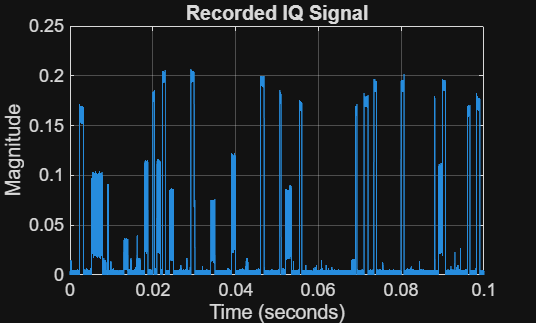


% Plot magnitude
t = (0:length(IQ)-1)/Fs;

figure;
plot(t,abs(IQ));
xlabel('Time (seconds)');
ylabel('Magnitude');
title('Recorded IQ Signal');
grid on;

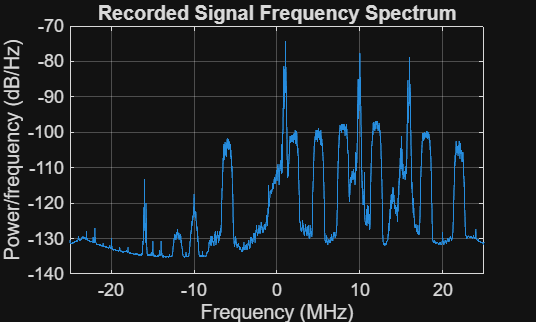


% Plot frequency spectrum
figure;
pwelch(IQ,hann(4096),2048,8192,Fs,'centered');
title('Recorded Signal Frequency Spectrum');

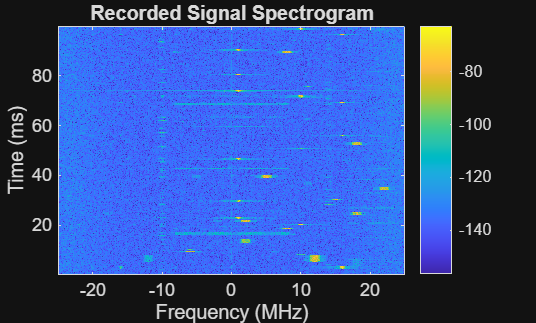


% Plot spectrogram
figure;
spectrogram(IQ,hann(1024),768,2048,Fs,'centered');
title('Recorded Signal Spectrogram');
colorbar;